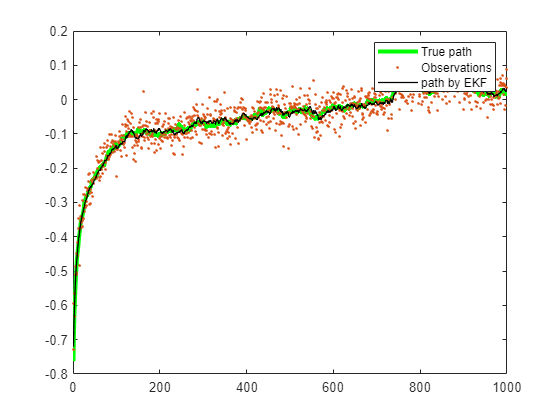

clear all ; clc
Xk =[];
Xhat =[];
xk=randn;
Yk=[];

Phat=0.1;
xhat=0;

sigmav2 = 0.00001;
sigmaw2 = 0.001;

for k= 1 : 1000

    vk = randn*sqrt(sigmav2);
    wk = randn*sqrt(sigmaw2);
    xk = sin(xk) + vk;
    yk = sin(xk) + wk;
    Xk = [Xk xk];
    Yk=[Yk yk];

    Fk=cos(xhat);
    xtemp=sin(xhat);
    Ptemp=Fk*Phat*Fk'+sigmav2;

    Hk=cos(xtemp);
    ytemp=sin(xtemp);
    S=Hk*Ptemp*Hk'+sigmaw2;
    K=Ptemp*Hk'/S;

    xhat=xtemp+K*(yk-ytemp);
    Phat=Ptemp-K*Hk*Ptemp;
    Xhat = [Xhat xhat];

end
figure
plot(Xk,'g-','LineWidth',3)
hold on
plot(Yk,'.')
hold on
plot(Xhat,'k-','LineWidth',1)
 legend('True path','Observations','path by EKF')